# Explore and Analyze Tornadoes from 2013

Welcome to your first live script. This script gives you the opportunity to visualize a large dataset and explore its contents. Follow the instructions provided in each section and complete the interactions. As you progress through the course, you'll learn how to implement the various pieces yourself.

Throughout this course you'll be working with historical data from storm events in the United States. The files include over 40 different types of storm events, and contain information such as geographic location, date, damage cost in dollars, injuries, deaths, and text descriptions of the storm. 

There is a lot of missing data. For example, many events affect a large area, so no specific location is provided. As you explore the data, you'll see these represented as `NaN`, which stands for "not a number." Dealing with missing data is an important skill covered later, so don't worry about NaN entries for now.

This script explores the tornado events of 2013. There are many tornadoes in the data set. Nearly all tornado events have information for the location and damage associated with them. This makes tornadoes a great place to start. 

## Part 1: Import the Data

This section imports the data using a function generated by the Import Tool. You'll learn how to do this Module 2.

- Click in this section to make it the active section. 

- In the **Live Editor** tab click **Run Section**.  

- Explore the table to get a feel for the contents. Click on a variable to preview the contents. The table contains many columns, so scroll horizontally to see all the data. 

- Click on the `Begin_Date_Time` variable. Select "Sort Oldest to Newest" to order the events chronologically. 

- Click on the "Update Code" button and run the section again. 

events = importStormData("StormEvents_2013.csv")

events = 59985×16 table
     Month         Event_Type          Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    

#### Data processing steps

As you explore new data, you'll typically discover there is some "clean-up" to perform. You won't know this in advance. So, while it looks like the first thing you do is clean the data, that comes after some initial exploration. You'll learn more about the steps below in Modules 3 and 4. 

- Click **Run Section** to perform the preprocessing steps and move to the next section.

% Put months in correct order
monthOrder = ["January", "February", "March", "April", "May", "June", "July",...
    "August", "September", "October", "November", "December"];
events.Month = reordercats(events.Month, monthOrder);
% Set missing Property and Crop Cost to $0
events.Property_Cost(ismissing(events.Property_Cost)) = 0;
events.Crop_Cost(ismissing(events.Crop_Cost)) = 0;
% Add total damage to the table
events.Total_Damage = events.Property_Cost + events.Crop_Cost;

**Description of code above**

- By default, the text in the "Month" variable of the table is ordered alphabetically. The code reorders the categories to match the calendar. This is not necessary but makes the visualizations easier to interpret. 

- Some events are missing information on the associated property and/or damage caused to property and crops. Missing cost is replaced with 0 as missing information likely means small or no damage to report.

- A new variable named `Total_Damage `is added to the table. This variable is the sum of `Property_Cost + Crop_Cost`.

## Part 2: Visualize the Locations of Tornadoes

### Plot all tornados above a damage threshold

The code below creates a plot of tornado locations on a map. The size of the markers represents the cost in dollars of the damage caused by the tornado. The slider sets a minimum value for total damage of an event to be included in the plot.  

- Click into this section to make it the active section.

- Click **Run Section** to visualize the results.

- Click on the map to make the figure active.

- Above the map Plus (+), Minus (-), and Home icons appear. Click the Plus icon to zoom in.

- Zoom in further and/or pan on the map by clicking the mouse and dragging the map.

- Click the Home icon to reset the view.

- Set a threshold for damage caused by adjusting the slider.

minDamage = 0;

There is no need to edit the code below. In Modules 3 and 4 you'll learn how to create visualizations and select subsets of data. Then in Module 5 you'll learn how to add an interactive control to interactively modify variable values.

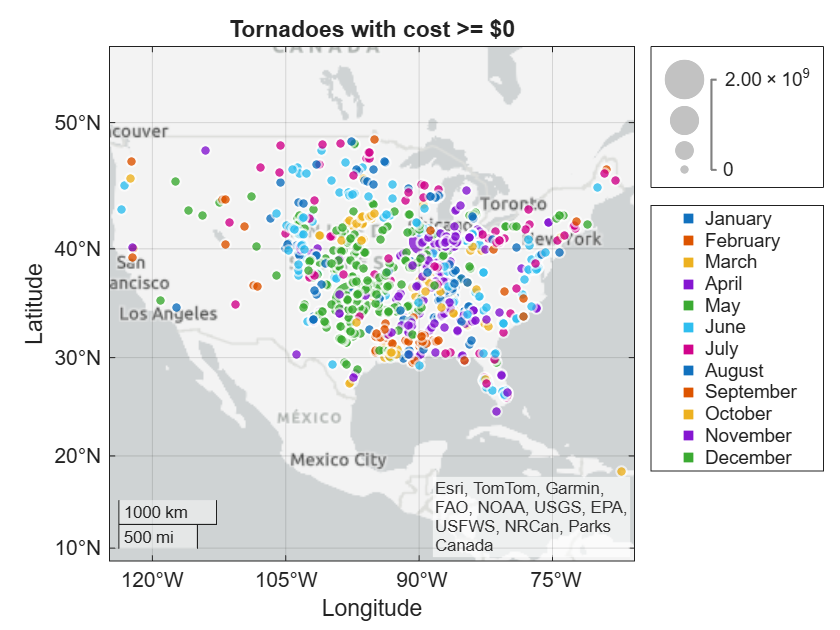

% Select tornadoes above a damage threshold set by the slider
tornadoes = events(events.Event_Type == "Tornado" & events.Total_Damage >= minDamage, :);
% Plot the results on a map
geobubble(tornadoes.Begin_Lat,tornadoes.Begin_Lon,tornadoes.Total_Damage, tornadoes.Month);
title("Tornadoes with cost >= $" + minDamage)

**Description of code above**

- A new table with only tornadoes above the damage threshold is created. 

- The location of tornadoes is plotted.

### Plot tornadoes for a given month

Below is a drop-down menu to explore the location of tornadoes for a given month. Observe how the number and location of tornadoes varies throughout the year. All tornadoes are treated as equal regardless of damage caused.

- Run this section.

- A new figure is created. Use the Minus icon in the plot tools to zoom out until the region visible is similar to the figure in the previous section.

- Click **Update Code**. This will set the axes limits so they don't change when you select a different month.

- Select `May` from the drop-down menu.

- Explore other months.

eventMonth = "March";

There is no need to edit the code below. The code recreates the tornadoes table so that all tornadoes are included. By the end of Module 3 you'll be able to select any Event_Type and create a new table of just that category.

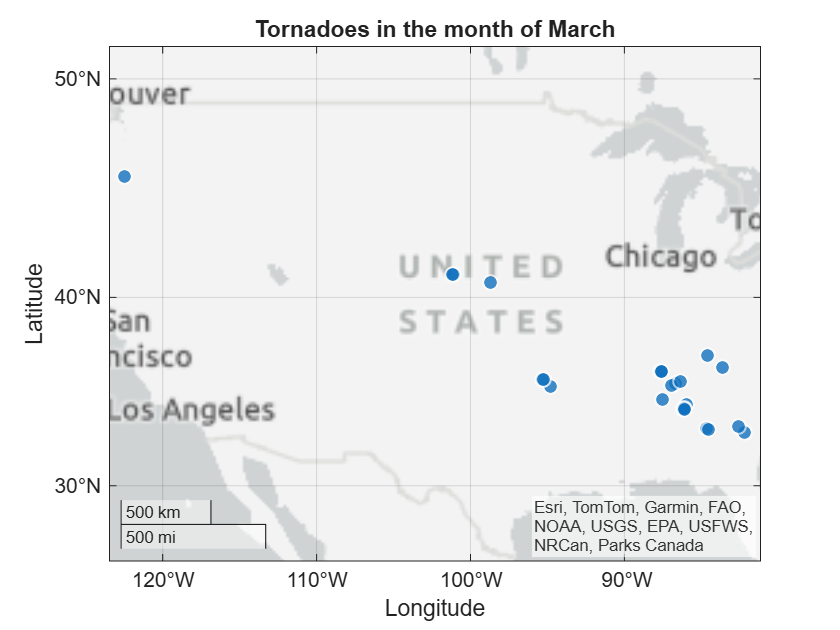

tornadoes = events(events.Event_Type == "Tornado", :);
tornadoes = tornadoes(tornadoes.Month == eventMonth, :);
geobubble(tornadoes.Begin_Lat,tornadoes.Begin_Lon);
title("Tornadoes in the month of " + eventMonth)

## Part 3: Calculate Group Summary Statistics

### Create a histogram of tornado events

In the section above, you may have noticed that some months have more tornadoes than others. This section creates a histogram to show the number of tornadoes by month.

- Run this section. Which month has the most tornadoes? Is there a tornado season?

tornadoes = events(events.Event_Type == "Tornado",:)

tornadoes = 1053×17 table
     Month     Event_Type      Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        Episode_Narrative                

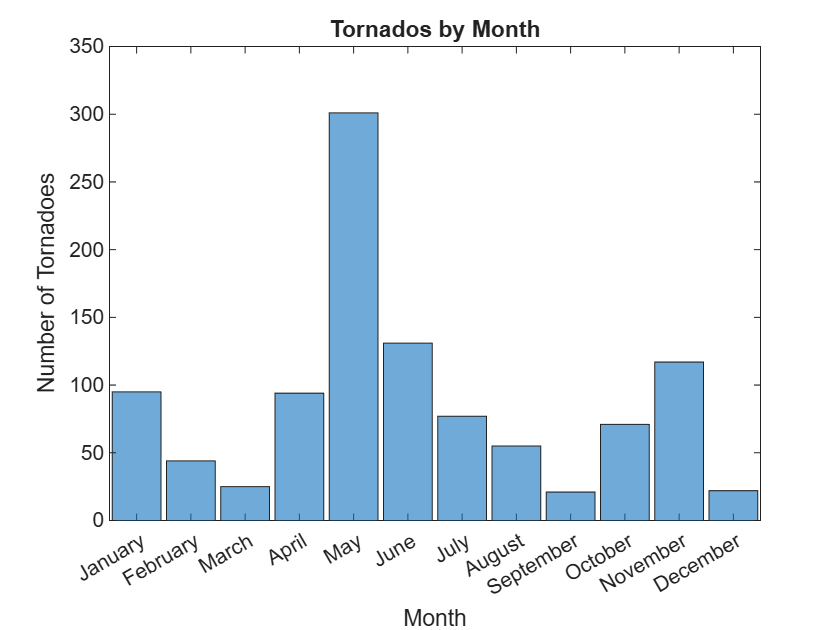

histogram(tornadoes.Month)
title("Tornados by Month")
xlabel("Month")
ylabel("Number of Tornadoes")

### Total damage by month

Looking at the histogram, the month of May had far more tornadoes than any other month. Now examine the damage caused by these tornadoes. 

- Run this section. A table showing the number of tornadoes for each month and the selected statistic is created. A bar plot shows the results.

- Use the drop-down menu to change the statistic calculated for each month.

stat = "sum";

There is no need to edit the code below. In Module 4 you'll learn how to calculate statistics on groups in your data. Here, the code calculates the chosen statistic for each month on the `Total_Damage` variable in the table.

tornadoes = events(events.Event_Type == "Tornado",:);
% Group tornadoes by month and calculate the selected stat
cost = groupsummary(tornadoes, "Month", stat, "Total_Damage")

cost = 12×3 table
      Month      GroupCount    sum_Total_Damage
    _________    __________    ________________

    January          95           8.8605e+07   
    February         44           4.0211e+07   
    March            25             1.37e+06   
    April            94           1.5928e+07   
    May             301           2.3525e+09   
    June            131           5.6485e+06   
    July             77           1.0251e+07   
    August           55           2.0513e+07   
    September        21             4.08e+05   
    October          71           1.0437e+07   
    November        117           1.0944e+09   
    December         22            8.468e+06   


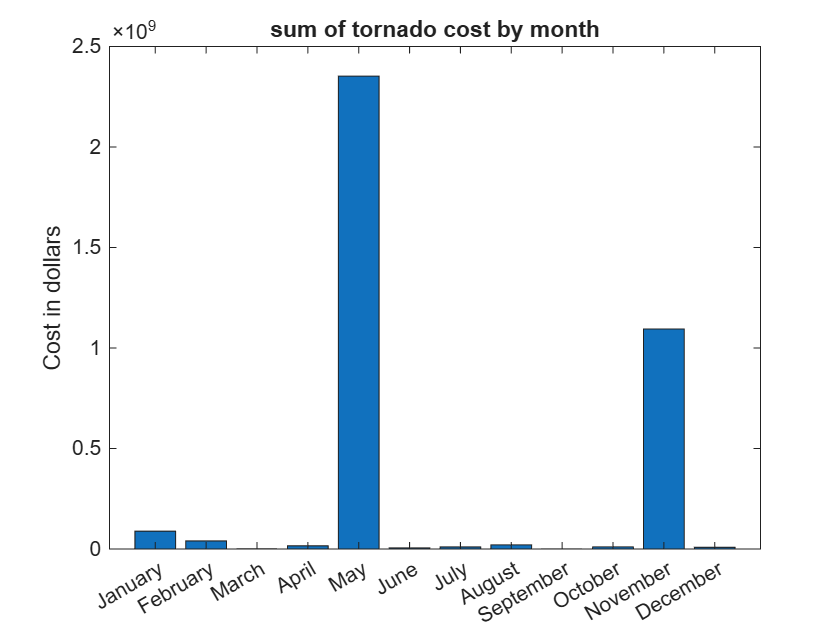

% View the results using a bar chart
bar(cost.Month, cost{:, end})
title(stat + " of tornado cost by month")
ylabel("Cost in dollars")

**Description of code above**

The `groupsummary` function returns a table. The table includes the number of events in each group and the statistic for the selected variable. In this example, the data is grouped by the `Month` variable. The statistic selected in the drop-down menu is applied to the `Total_Damage` variable. The result is added to the last column of the table. A bar plot is used to visualize the result.

## Closing Remarks

Notice how quickly creating a variety of visualizations provided an overview of lots of data. What have you learned about tornadoes in the United States in 2013? Hopefully you gained a feel for the data. This is important later when trying to evaluate predictive models. Without a feel for the data, it's difficult to look at the output of a complex model and determine if the results are reasonable.

For now, you can state that in 2013:

- The frequency of tornadoes was less during the winter months than late spring/early summer

- Winter tornadoes tend to be in the southern United States

- An extremely damaging tornado occurred in November

Maybe you have a lot more questions. For example, what states are most affected? What do the results look like for different years? This script just looks at tornadoes, what about all the other storm events? The fun, and challenging, aspect of having lots of data is trying to explore all the possible questions and relationships. By the end of this course you'll have the skills to answer these questions and more.

**Hint. **You can look at other years by changing the year in the filename in the first line of code!